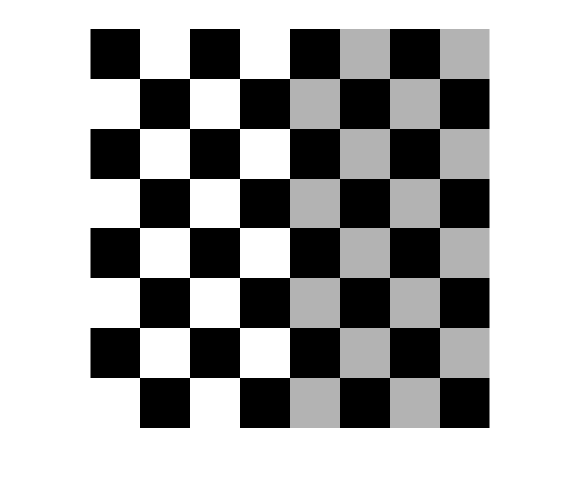

f = checkerboard(50);
imshow(f);

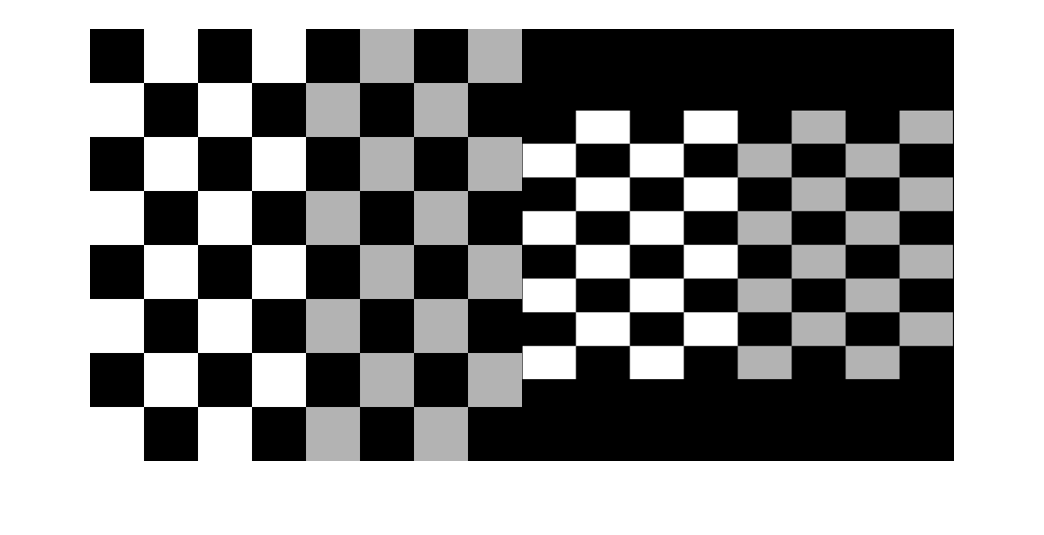

sx = 2; sy = 1.25;
T = [sx 0 0
     0 sy 0;
     0 0 1];
t1 = affinetform2d(T);
g1 = imwarp(f, t1);
montage({f, g1})

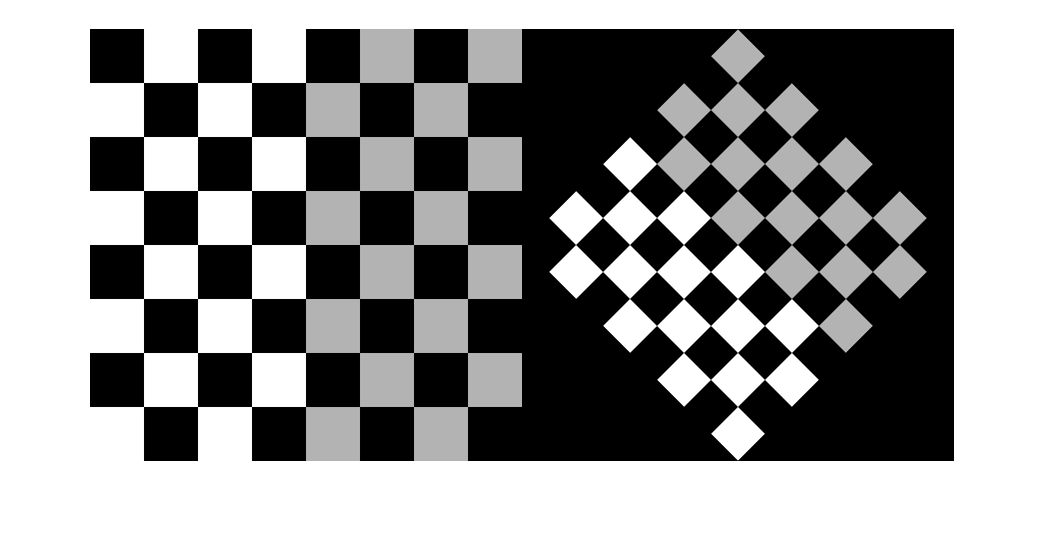

theta = pi/4;
T2 = [cos(theta) sin(theta) 0;
      -sin(theta) cos(theta) 0;
      0           0           1];
t2 = affinetform2d(T2);
g2 = imwarp(f, t2);
montage({f, g2})

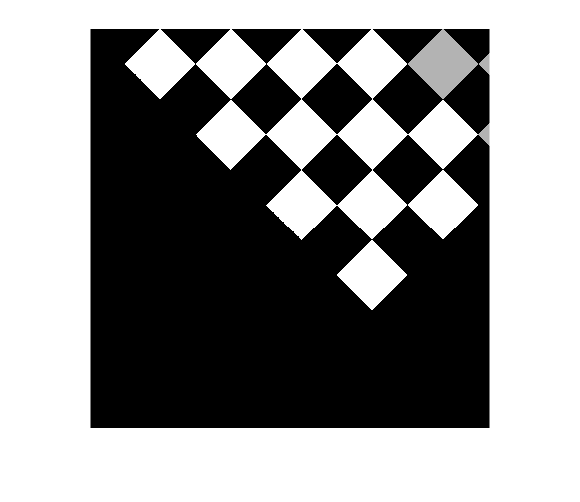

theta = pi/4;
T_matrix = [cos(theta) sin(theta) 0;
      -sin(theta) cos(theta) 0;
      0           0           1];
T_matrix = inv(T_matrix);

I_trasformed = zeros(size(f));
Rows = size(f,1);
Cols = size(f,2);
for i = 1:1:Rows
    for j = 1:1:Cols
        T_cords = [i j 1] * T_matrix;
        T_x = T_cords(1);
        T_y = T_cords(2);
         if T_x <= 0 || T_x > Rows || T_y <= 0 || T_y > Cols
            continue
         end
         T_x = ceil(T_x);
         T_y = ceil(T_y);
        I_trasformed(i, j) = f(T_x,T_y);
    end
end
imshow(I_trasformed, [])

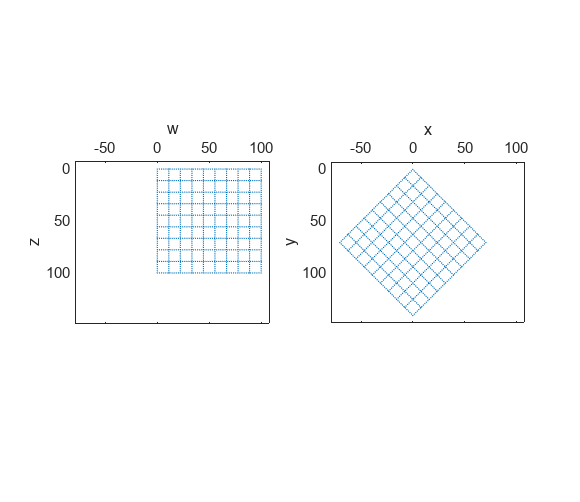

tform2 = maketform("affine", T2);
vistform(tform2, pointgrid([0 0; 100 100]))